%addpath 'C:\Users\anonf\OneDrive\uni\phys project\matlab\iwave\development\matlab'

f_sampling = 250e6; % Hz
t_end = 0.05; % secs

t_step = 1/f_sampling;
t = 0 : t_step : t_end;

%% constants
c = 3e8; % m/s
h_eV = 4.136e-15; % eV
k_B = 1.38065e-23; % m2 kg s-2 K-1
h = 6.62607015e-34; % m2 kg / s
hbar_times_c = 2e-7; % eV m

%% parameters
axion_rest_energy = 2e-6; % eV/c2
axion_velocity = 240e3; % m/s
T = 10e-3; % K
axion_power = 1.5e-21; % W, from eq 2.28 of Daw thesis

% noise powers 1e-16 2e-16

%% axion signal params
f_0 = axion_rest_energy / h_eV % Hz, default axion

f_0 = 4.8356e+08

axion_linewidth = f_0 * 1e-6

axion_linewidth = 483.5590

axion_Q = f_0 / axion_linewidth;

f_0 = f_0 / 20 % heterodyne

f_0 = 2.4178e+07


de_broglie_wavelength = 2*pi * hbar_times_c / (axion_rest_energy * axion_velocity/c);
t_coherence = de_broglie_wavelength / axion_velocity;

%% generate axion frequency
f_axion = generate_axion_frequency(t, f_sampling, t_coherence, f_0, axion_linewidth);

%% generate signal and noise
signal = generate_axion_signal(t, f_sampling, f_axion, axion_power);
noise_power = calculate_noise_power(f_sampling, T);
noise = generate_thermal_noise(t, f_sampling, noise_power);

band_width = 750;
f_0_for_filter = f_0 - 1000;
band = [f_0_for_filter-band_width/2, f_0_for_filter+band_width/2]

band = 1.0e+07 *

    2.4177    2.4177


displayband = [f_0 - 20*axion_linewidth, f_0 + 20*axion_linewidth]

displayband = 1.0e+07 *

    2.4168    2.4188



SNR_before = bandpower(signal)/bandpower(noise)

SNR_before = 9.4603e-05

% now we've decided the best filtering, do it
wo = f_0_for_filter / (f_sampling/2);  
bw = band_width / (f_sampling/2);
[b, a] = iirpeak(wo, bw);
iwave_input_f = filter(b, a, signal + noise);

Arrays have incompatible
sizes for this operation.

Related documentation

display_spectra(signal + noise, iwave_input_f, f_sampling, displayband);
xline(band)

power_in_band = bandpower(iwave_input_f, f_sampling, band)

power_in_band = 1.3926e-22

power =         bandpower(iwave_input_f, f_sampling, [0, f_sampling/2.001])

power = 4.3251e-22

fraction_of_power_in_band_after = power_in_band / power

fraction_of_power_in_band_after = 0.3220

%% run iwave
tau_iwave = 1e-5; % before adding noise
tau_iwave = 3e-4;
tau_iwave = 3e-4; % for 1* mult
%tau_iwave = 1e-4
%tau_iwave = 30e-4
%tau_iwave = 15e-4
%tau_iwave = 3.8e-4/0.1;
%tau_iwave = 20e-4; % for 10* mult

% front to chop off
% start_secs = 4 * tau_iwave;
start_secs = t(end)/4;
assert(start_secs < t(end)/3)
start = round(start_secs * f_sampling);

[f_iwave, amp] = run_iwave(iwave_input_f, f_sampling, f_0, tau_iwave);

% don't need to plot every single point
div = 1000;

slice = (1:div:length(t));
t_small       = t(slice);
f_axion_small = f_axion(slice);
f_iwave_small = f_iwave(slice);
amp_small = amp(slice);

start = round(start / div)

start = 3125

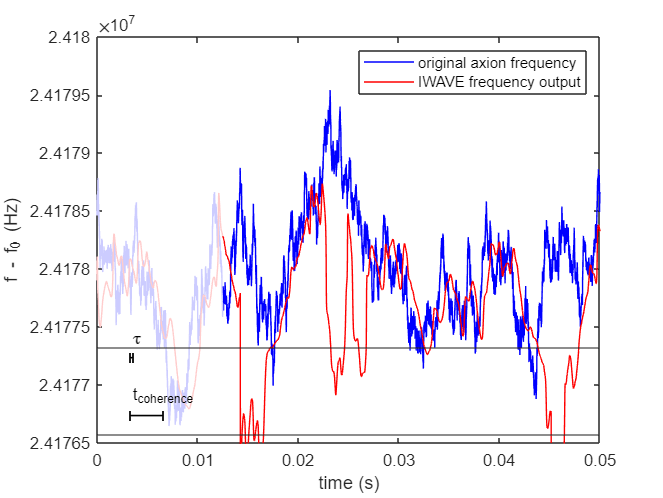

% plot iwave before and after
figure
%adstyle(8, 8);

plot(t_small(start:end), f_axion_small(start:end)-0, 'Color', [0,0,1], 'DisplayName','original axion frequency')
y_lim = ylim();
hold on
plot(t_small(1:start),   f_axion_small(1:start)  -0, 'Color', [0.8,0.8,1], 'HandleVisibility','off')
plot(t_small(start:end), f_iwave_small(start:end)-0, 'Color', [1,0,0], 'DisplayName','IWAVE frequency output')
plot(t_small(1:start),   f_iwave_small(1:start)  -0, 'Color', [1,0.8,0.8], 'HandleVisibility','off')
ylim(y_lim)
x_lim = xlim();
legend()
xlabel('time (s)')
ylabel('f - f_0 (Hz)')

y_width = y_lim(2) - y_lim(1);
x_width = x_lim(2) - x_lim(1);

x_start = x_lim(1) + x_width/15;
y_1 = y_lim(1) + y_width/15;
y_2 = y_1 + y_width/7;

plot([x_start, x_start + t_coherence], [y_1, y_1], '-|', 'Color','black', 'LineWidth',1, 'HandleVisibility','off')
plot([x_start, x_start + tau_iwave], [y_2, y_2], '-|', 'Color','black', 'LineWidth',1, 'HandleVisibility','off')

text(x_start, y_1 + y_width/20, 't_{coherence}')
text(x_start, y_2 + y_width/20, '\tau')

yline(band, 'HandleVisibility','off')

%saveas(gca, 'figures/chop.eps', 'epsc');

% now remove the start as it can go a bit off
% start_samples = start_secs * f_sampling;
% t       = t      (start_samples:end);
% f_iwave = f_iwave(start_samples:end);
% f_axion = f_axion(start_samples:end);
% signal  = signal (start_samples:end);
% noise   = noise  (start_samples:end);

% find avg diff between iwave and original
% avg_dist_dynamic = rms(f_iwave - f_axion);
% Qmax_dynamic = 2 * f_0 / avg_dist_dynamic;
% 
% avg_dist_static = rms(f_0 * ones(size(t)) - f_axion);
% Qmax_static = 2 * f_0 / avg_dist_static;